clear, clc, close all

% trainset 경로
path0 = "C:/Users/" + getenv('username') +"/Desktop/DCASE2024-Task10-Dataset/";
loc_name = "loc1/";     % "loc3";
train_name = "train.csv";

train_path = path0 + loc_name + train_name;
data_info = readtable(train_path);
len_data = height(data_info);

data_nn = 1; % 20;
label_name = ["car_l2r", "car_r2l", "cv_l2r", "cv_r2l"];
label = [data_info.car_left(data_nn) data_info.car_right(data_nn) data_info.cv_left(data_nn) data_info.cv_right(data_nn)]

label =      1     1     1     0


filepath = path0 + loc_name + data_info.path{data_nn}

filepath = "C:/Users/yeon/Desktop/DCASE2024-Task10-Dataset/loc1/train/00000.flac"

[sig, fs] = audioread(filepath);
tt = (0:length(sig)-1)/fs;

sig = sig/(max(abs(sig(:))));

disp("총 차량 갯수 : " + sum(label));

총 차량 갯수 : 3


disp(label_name + " = " + label);

    "car_l2r = 1"    "car_r2l = 1"    "cv_l2r = 1"    "cv_r2l = 0"



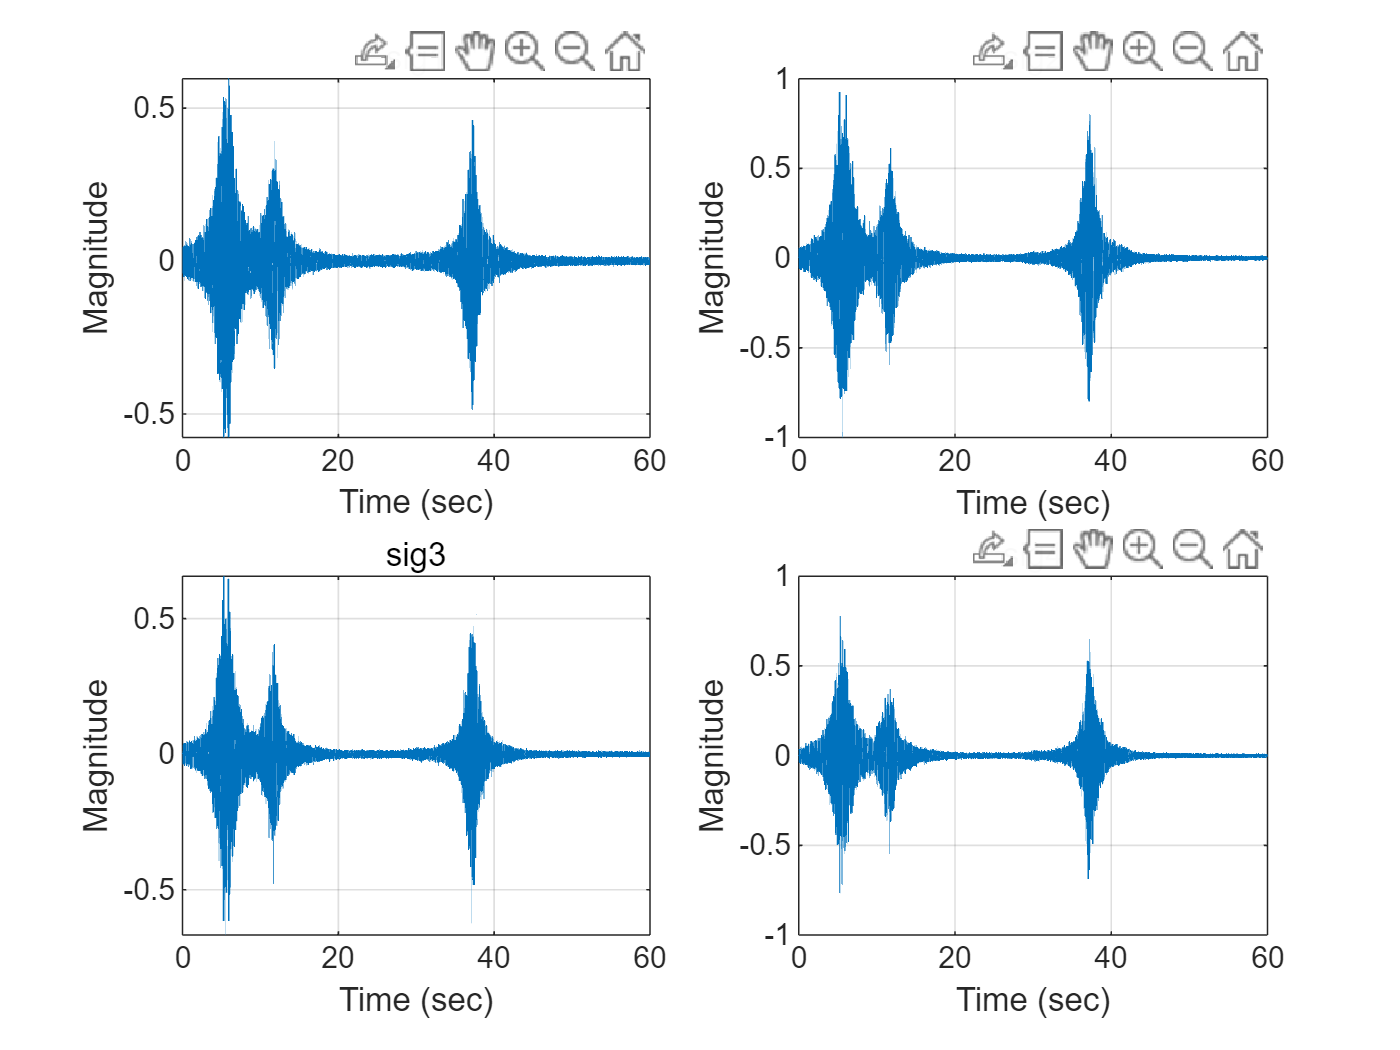

sig_name = {'sig1', 'sig2', 'sig3', 'sig4'};
figure(1), % title(filepath + " 4채널 소리 데이터 그래프")
for nn = 1:4
    subplot(2,2,nn), plot(tt, sig(:,nn)), grid
    title(sig_name{nn}), xlabel('Time (sec)'), ylabel('Magnitude')
end

fframe = 2^10;
delay = fframe/4;
sum_sig = sum_2sig_with_delay(sig, delay);

sthds = {};

tic
parfor nn = 1:6
    sthds{nn} = stHD(sum_sig(:,nn), fs, fframe);
end
toc

경과 시간은 0.389522초입니다.


size(sthds{1})

ans =         1024        1874


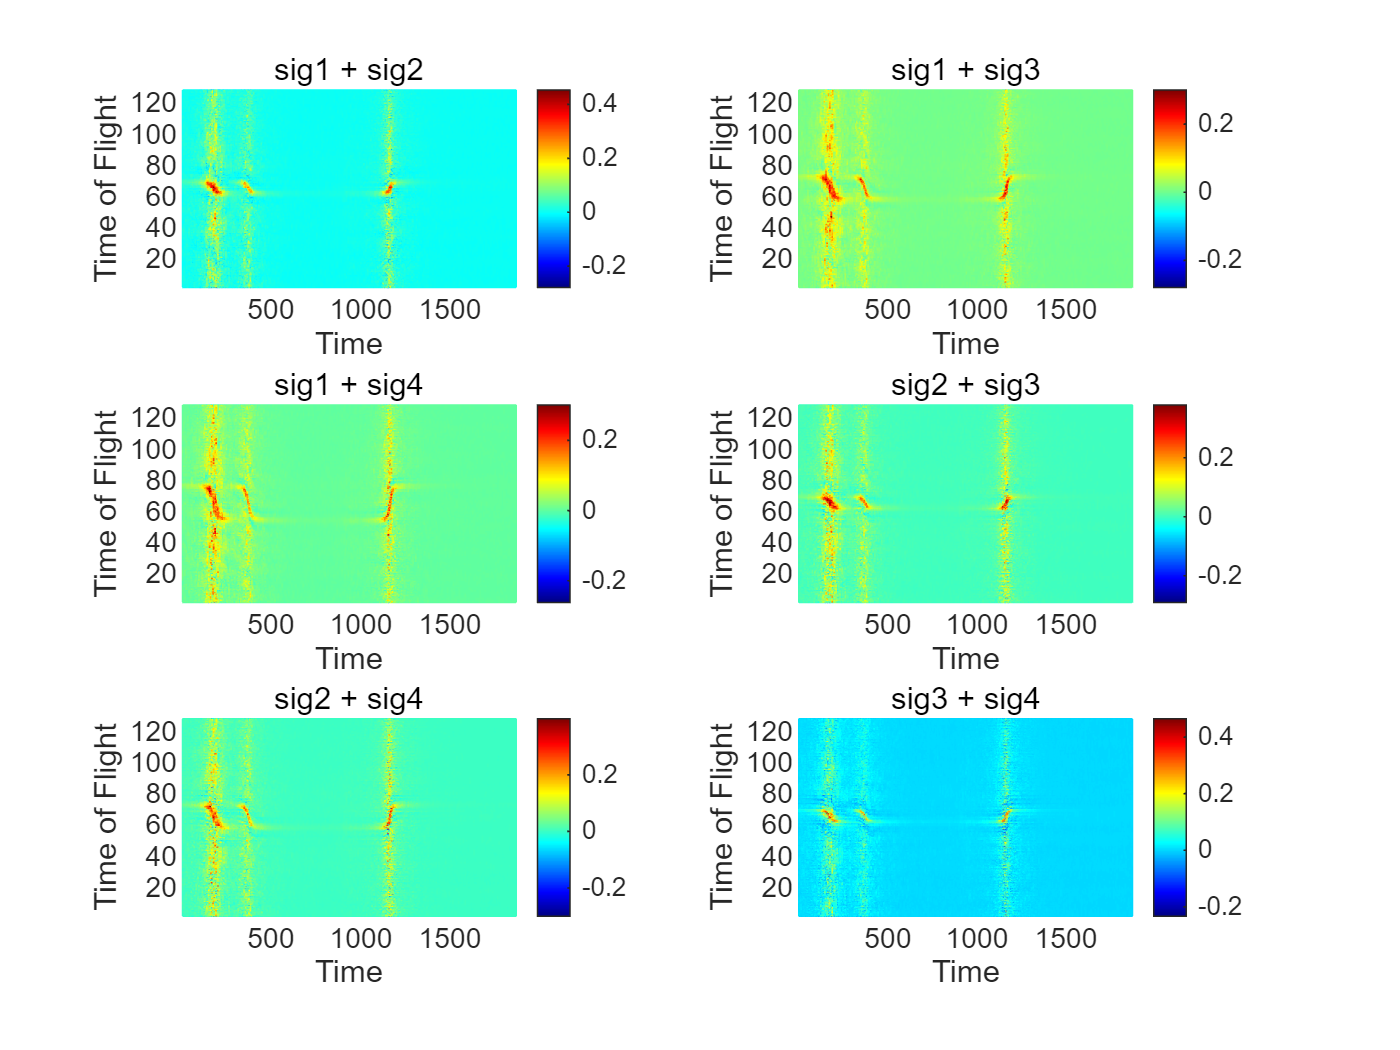

sig_name = {'sig1 + sig2', 'sig1 + sig3', 'sig1 + sig4', 'sig2 + sig3', 'sig2 + sig4', 'sig3 + sig4'};
% mesh_xlim = 1:fframe/2;
mesh_xlim = fframe/4-fframe/16+1:fframe/4+fframe/16;

figure('Name', "STHD" + nn),
for nn = 1:6
    sthd = sthds{nn};
    sthd = sthd(mesh_xlim,:);

    subplot(3,2,nn),
    mesh(sthd, 'FaceColor', 'flat'), colormap(jet), colorbar, view([0 90]),
    title(sig_name{nn}), xlabel('Time'), ylabel('Time of Flight')
    xlim([1 1874]), ylim([1 128])   
end


disp("총 차량 갯수 : " + sum(label));

총 차량 갯수 : 3


disp(label_name + " = " + label);

    "car_l2r = 1"    "car_r2l = 1"    "cv_l2r = 1"    "cv_r2l = 0"



## Spectrogram 그리기

stft로 계산하고 크기, 제곱을 mag2db를 하면 되나?

stfts = {};
tic
parfor nn = 1:4
     S = stft(sig(:,nn)+eps, fs, 'Window', hann(fframe,'periodic'), 'OverlapLength', fframe/2, 'FFTLength', fframe, 'FrequencyRange', 'onesided');      
     stfts{nn} = mag2db(abs(S)+eps);
end
toc

경과 시간은 0.150972초입니다.


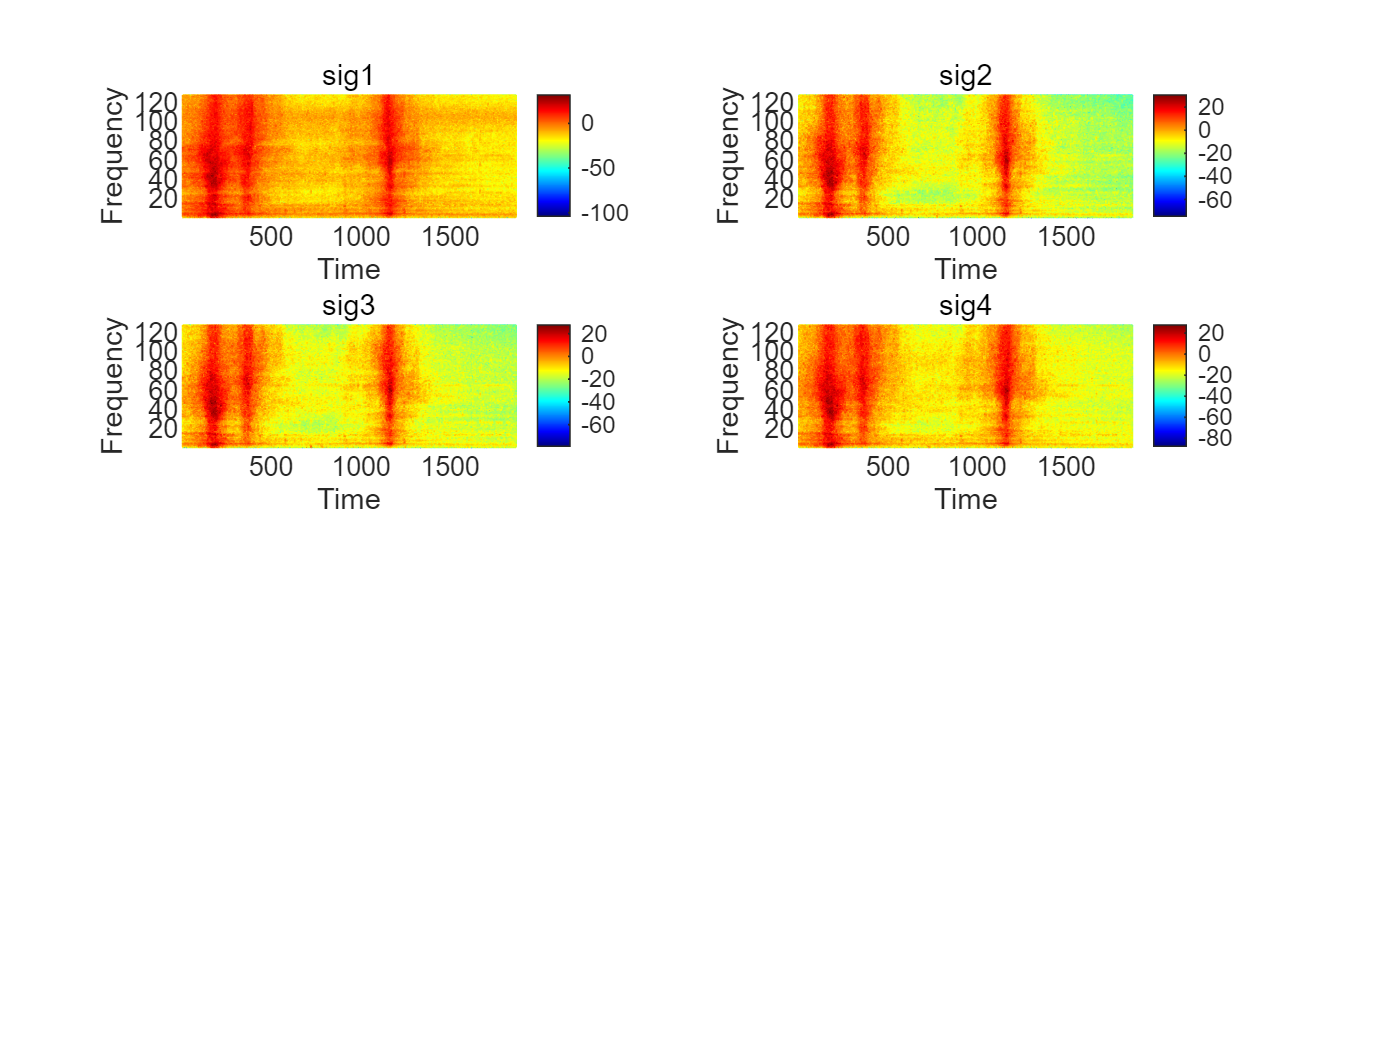

sig_name = {'sig1', 'sig2', 'sig3', 'sig4'};

figure("Name", loc_name+"3"), %sgtitle("Spectrogram 그림 - " + label_name)
mesh_xlim = 1:fframe/8;

for nn = 1:4
    subplot(2,2,nn),
    mesh(stfts{nn}(mesh_xlim,:), 'FaceColor', 'flat'), colormap(jet), colorbar, view([0 90]),
    title(sig_name{nn}), xlabel('Time'), ylabel('Frequency')
    xlim([1 1874]), ylim([1 128])
end